# Temperature Dependence of Absorption Spectrum

Author: André Silva Correia

## Initialisation

init;

### Species

species = "OH";
colls_path = "D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\lifmat\input-data\air+NO.csv";

### Flame Characteristics

    Tflame - flame temperature profile at different $\phi$

    Y_species - target species molar concentration

    phi - equivalenc ratio $\phi$

load("FF_T_OH.mat");
ph = phi(4);    % Flame equivalence ratio

### Temperature Range [K]

Tstep = 100;
Trange = [1100 2100];
Tset = Trange(1):Tstep:Trange(2);

### Laser parameters

unit = 'nm';
%224.97 - 225.22 ~ 44400 - 44450
startwn = 279.5 ;
checkWnum(unit,startwn);
endwn = 288;
checkWnum(unit,endwn);
step = 0.0001;
dnuGL = 0.001;    % Laser FWHM Gaussian
dnuLL = 0.001;    % Laser FWHM Lorentzian
I_filter = 0.65;    % Filter out lines without sufficient itensity to be detected

### Environment

N = 1;        % Number density [1/m^3]
L = 0.05;        % Path length [m]
P = 1;        % Pressure [bar]

dnuL = 0.01;
dnuSh = 0;

Tenv =  1800;    % Environment Temperature to analyse the itensities to be filtered [k]

### Plot Settings

T_plot_step = 100;
T_plot_range = [1100 2100];

## **Collisions data and Absorption spectrum filter**

colls =  collisions(species);

absWnum = startwn:step:endwn;
plotWnum = absWnum;

if strcmpi(unit,'nm') 
    absWnum = convWnumWlen(absWnum);
    dnuGL = convWnumWlen(dnuGL,endwn);
    dnuLL = convWnumWlen(dnuLL, endwn);
end

[aux_linelist, Z, n, ~,MM] = selectLines(species,absWnum);

if n == 0    
    warning("No lines found.")
    return;
end

if ~isempty(colls)
    gas = loadGasComposition(colls_path);
    
    [dnuL, dnuSh] = collisionalBroadening(gas, colls, P, Tenv);
    [quen,aux_linelist] = quenchRate(gas, colls, Tenv, P,MM, linelist);
 
end
varargin   = {'Z', Z};

aux_spec = absorptionSpec(absWnum, aux_linelist, MM, Tenv, dnuGL, dnuLL,Z=Z,...
      limit=12, N=N, L=L, dnuL=dnuL, dnuSh=dnuSh, normalize=false);


I_thesh = I_filter*max(aux_spec);
[aux_spec_peak, aux_absWnum_peak, peakWidths] = findpeaks(aux_spec, absWnum);

linelist = {};
for i = 1:size(aux_spec_peak,2)
    if aux_spec_peak(i) >= I_thesh
        for j = 1:size(aux_linelist,1)            
            if (aux_linelist{j}.nu0 >= (aux_absWnum_peak(i)-peakWidths(i))) && (aux_linelist{j}.nu0 <= (aux_absWnum_peak(i)+peakWidths(i)))
                linelist = [linelist; aux_linelist{j}];
            end
        end
    end
end


## **Absorption spectrum**

for i = 1:size(Tset,2)
    if ~isempty(colls)
        gas = loadGasComposition(colls_path);
        
        [dnuL, dnuSh] = collisionalBroadening(gas, colls, P, Tset(i));
        [quen,linelist] = quenchRate(gas, colls, Tset(i), P,MM, linelist);
     
    end
    varargin   = {'Z', Z};
    
    aux_spec = absorptionSpec(absWnum, linelist, MM, Tset(i), dnuGL, dnuLL,Z=Z,...
          limit=12, N=N, L=L, dnuL=dnuL, dnuSh=dnuSh, normalize=false);
    
    [spec_peak(i,:), absWnum_peak] = findpeaks(aux_spec, absWnum, "MinPeakHeight",I_thesh*0.1);

    if strcmpi(unit,'nm') 
        aux_spec = fliplr(aux_spec);
    end
    spec(i,:) = aux_spec;
end


## Temperature Dependence

Temperature Dependence weighted average:


$${\left\langle \left|\frac{dF\left(T_{i\;} ,\lambda_j \right)}{{dT}_i }\right|\right\rangle }_{N_{\mathrm{OH}} }$$


i_flame = find(phi == ph);

[~, aux_i] = unique(Tflame{i_flame});
Tflame{i_flame} = Tflame{i_flame}(aux_i);
Y_OH{i_flame} = Y_OH{i_flame}(aux_i);
Y_OHflame = interp1(Tflame{i_flame},Y_OH{i_flame},Tset,'spline');
Y_OHflame(Y_OHflame<0) = 0;

for i = 1:size(absWnum_peak,1)
    dI(i) = sum(abs(diff(spec_peak(:,i)')./diff(Tset)).*Y_OHflame(2:end))/trapz(Y_OHflame(2:end));
end

[dI, aux_i] = sort(dI);
absWnum_peak = absWnum_peak(aux_i);

## Result

### Plot

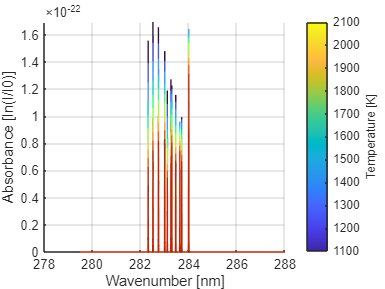

T_plot_set = T_plot_range(1):T_plot_step:T_plot_range(2);
T_plot_norm = (T_plot_set -T_plot_range(1))/(T_plot_range(2) -T_plot_range(1));

figure
hold on

for i = 1:size(T_plot_set,2)-1
    color = turbo(256);
    line_color = color(round(T_plot_norm(i) * 255) + 1, :);
    % Connect the points with plot
    plot(plotWnum, spec(i,:), 'Color', line_color, 'LineWidth', 0.5);
end

hold off
grid
cb = colorbar();
ylabel(cb,'Temperature [K]')
clim([min(T_plot_set) max(T_plot_set)])
ylim([0 inf])
%xlim([282.2 283.8])
xlabel('Wavenumber [nm]');
ylabel('Absorbance [ln(I/I0)]');

### Least dependant on Temperature:

for i=1:size(absWnum_peak,1)
    fprintf('%d: %.2f cm-1 = %.3f nm\n', i, absWnum_peak(i), convWnumWlen(absWnum_peak(i)));
    fprintf('    dI_dT = %.2f \n', dI(i)/dI(1));
end

1: 35210.66 cm-1 = 284.005 nm


    dI_dT = 1.00 


2: 35256.47 cm-1 = 283.636 nm


    dI_dT = 1.50 


3: 35246.66 cm-1 = 283.715 nm


    dI_dT = 1.61 


4: 35321.14 cm-1 = 283.117 nm


    dI_dT = 1.87 


5: 35277.45 cm-1 = 283.467 nm


    dI_dT = 1.89 


6: 35297.66 cm-1 = 283.305 nm


    dI_dT = 2.00 


7: 35302.38 cm-1 = 283.267 nm


    dI_dT = 2.03 


8: 35420.39 cm-1 = 282.323 nm


    dI_dT = 2.36 


9: 35334.42 cm-1 = 283.010 nm


    dI_dT = 2.40 


10: 35210.26 cm-1 = 284.008 nm


    dI_dT = 2.47 


11: 35395.46 cm-1 = 282.522 nm


    dI_dT = 2.64 


12: 35366.93 cm-1 = 282.750 nm


    dI_dT = 2.64 
